# Project 1: Speech Synthesis and Perception with Envelope Cue

**张怡程 马文骁 高进 陈嘉祺**

## Introduction:

###     1.Basic idea of speech synthesis:

    The common communication devices based on digital circuits can only handle with discrete signal. However, the energy distribution of the human voice wavefrom in the frequency domain is relatively continuous. Therefore, directly transmitting without any processing will inevitably lead to distortion.

    The solution to this problem is speech synthesis whose basic idea is shown in *Figure 1.*

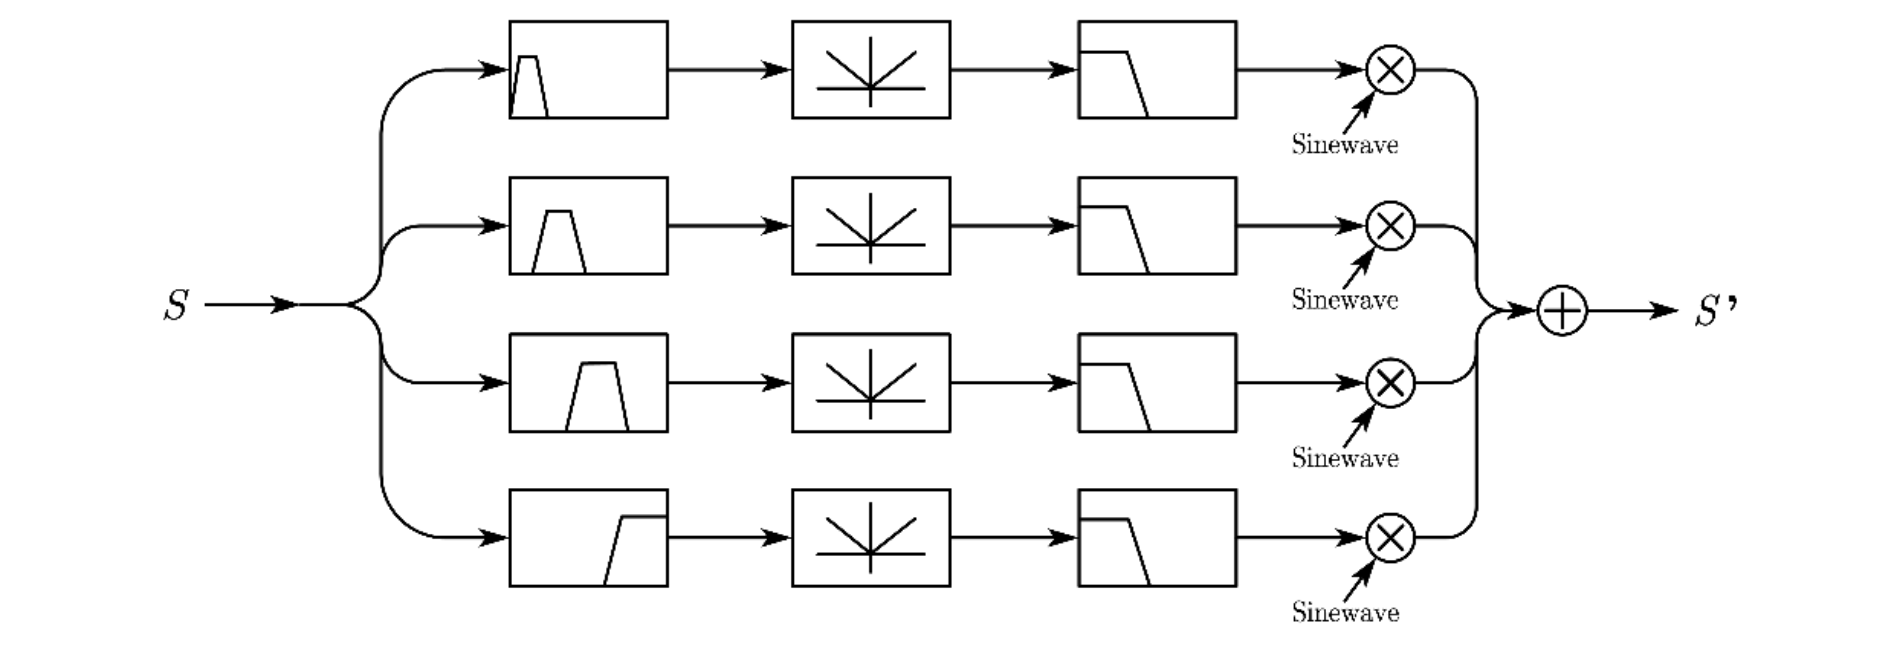

*Figure 1: Basic Idea of Speech Synthesis*

    The system uses a series of band-pass filters to divide the frequency spectrum of the input signal. For each of the fragments, do full-wave rectification and low-pass filtering to get the envelopes. Then, the sum of the multiplications of the envelopes and the corresponding sinewaves is the speech signal we want.

###     2. The Principle of Butterworth low-pass/band-pass filter

    The Butterworth filter is a type of signal processing filter designed to have as flat a frequency response as possible in the passband. It is also referred to as the maximally flat magnitude filter. The frequency response of the Butterworth filter is maximally flat (i.e. has no ripples) in the passband and rolls off towards zero in the stopband. The Butterworth filter rolls off more slowly around the cutoff frequency than the Chebyshev filter or the Elliptic filter, but without ripple.

###     3. The Introduction of the Filter Function of our Project

    To mimic the human cochlea, we used the frequency distribution function of the cochlea to divide the spectrum of the input signal.


$$f=165\ldotp 4\times \left({10}^{0\ldotp 06\bullet d} -1\right)$$
 

    Then the above speech synthesis principle and  Butterworth low-pass filter are used to obtain the target speech signal.

    We define the function as

*y=voiceSynthesize(x,N,n1,n2,fcut,fs)*

    You just need to input the SSN, number of the bands, levels of the low-pass/band-pass filter, cutoff frequency and sampling frequency to get the speech signal y.

###     4. The Principle of extracting speech envelope waveform

        Acrooding to Hilbert Transformation, signals can be decomposed into the product of an envelope and a fine-structure. To obtain the envelope of signals, we firstly retificate the signal to get the full wave and process the full wave by a low-pass filter.

###     5. The Principle of generate Speech-Shape Noise

    Speech-Shaped Noise (SSN) can be obtained by white noise processed by spectral filter. In this project, we get the frequency energy distribution of the input signal to generate the correspoinding filter. After that, generate white noise and feed it into a filter to get speech-shaped noise.

###     6.Principle of energy normalization

    Energy normalization:


$$\textrm{norm}\left(\textrm{signal}\right)=\sqrt{E_{\textrm{signal}} }$$


 
$$y\prime =\frac{y}{\textrm{norm}\left(y\right)}$$


    Signal-to-noise ratio (abbreviated SNR or S/N) is a measure used in science and engineering that compares the level of a desired signal to the level of background noise. It is defined as the ratio of signal power to the noise power.


$$\textrm{SNR}=20\log_{10}^{\sqrt{\frac{E_{\textrm{signal}} }{E_{\textrm{noise}} }}}$$


###     7.Observing signal characteristics: Spectrogram

    Both time-domain and frequency-domain representations of speech signals have their limitations. Time-domain plots depict the waveform variations of speech signals over time, but they may not be sufficiently intuitive for complex sound structures and rapidly changing frequency components, often susceptible to noise interference. Frequency-domain plots, on the other hand, display signal distribution across different frequencies but may not convey temporal information effectively. In contrast, spectrograms, combining both time and frequency information, offer a more comprehensive view of speech signal characteristics. Spectrograms are typically more accessible and are particularly valuable for analyzing speech, music, acoustic research, and related fields as they provide an intuitive visualization of how frequency components in the signal change over time, offering richer information and interpretability.

    The example of the spectrogram is shown in figure2. The X-axis represents time, the Y-axis represents frequency, and the color indicates signal intensity. Through the spectrogram, we can clearly observe the changes of the signal in both time and frequency domains, facilitating a better understanding of the signal's characteristics and structure.

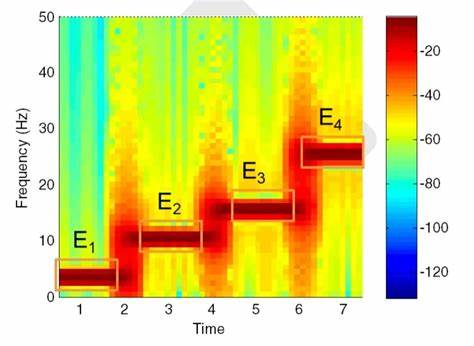

Now we load the object sound:

[x1,fs]=audioread(".\resource\C_01_01.wav");
[x2,~]=audioread(".\resource\C_01_02.wav");
x1=x1';
x2=x2';

%sound(x1,fs)

fcut=50;
figure
set(gcf, 'Position', [100, 100, 400, 140]);
plot(xTime(x1,fs),x1),title('Original Signal'),xlabel('t(s)')
plotSpectrum(x1,fs,5,1,'Spectrum of Original Signal'),xlabel('f(Hz)')
plotSpectrogram(x1,fs,"原音频信号的谱图")
SSN=createSSN(x1,fs);

## Result and Analysis

### Task 1 

**Restatement**

- Set LPF cut-off frequency to 50 Hz.

- Implement tone-vocoder by changing the number of bands to N=1, N=2, N=4, N=6, and N=8.

- Save the wave files for these conditions, and describe how the number of bands affects the intelligibility (i.e., how many words can be understood) of synthesized sentence.

**Verification**

    We now examine the effect of low-pass/band-pass Butterworth filter:

[b,a]=butter(4,800/(fs/2),'low');[H,w]=freqz(b,a);
subplot(2,1,1),plot(w.*(pi*fs/2),abs(H)),title('Effect of Butterworth Filters'),subtitle('LPF: 800Hz'),xlim([0,30000])
[b,a]=butter(4,[800,1600]/(fs/2),"bandpass");[H,w]=freqz(b,a);
subplot(2,1,2),plot(w.*(pi*fs/2),abs(H)),subtitle('BPF: 800~1600Hz'),xlabel('Frequency(Hz)'),xlim([0,30000])

The effect is indeed what we expect.

**Analysis:**

    Figures 1 and 2 represent the temporal and spectral characteristics of the synthesized speech signals, where N takes values of 1, 2, 4, 6, and 8. Figure 3 displays the spectrogram of the synthesized speech signal. To further investigate the effect of the number of frequency bands on sound reconstruction, a wider range of values for N, including 1, 2, 4, 6, 8, 20, 50, 100, 200 and 400, were considered for the spectrogram.

    Comparing the images with different values of N to the image of the original speech signal reveals that as N increases, the synthesized signal is better able to faithfully reproduce the original signal. One possible explanation is that as the number of frequency bands increases, the fine details and characteristics of the original signal can be better extracted, which is advantageous for the subsequent signal reconstruction.

    However, when N takes excessively large values, there tends to be distortion in the synthesized speech signal. Through comparison, it has been observed that N=100 is able to provide relatively better restoration of the original speech signal.

n1=4;n2=4;

We first observe the envelopes of the signals:

y1e=voiceEnvelope(x1,1,n1,n2,50,fs);
y2e=voiceEnvelope(x1,2,n1,n2,50,fs);
y3e=voiceEnvelope(x1,4,n1,n2,50,fs);
y4e=voiceEnvelope(x1,6,n1,n2,50,fs);
y5e=voiceEnvelope(x1,8,n1,n2,50,fs);

plotTimeGraph(y1e,fs,5,1,'N=1 Envelope')
plotTimeGraph(y2e,fs,5,2,'N=2 Envelope')
plotTimeGraph(y3e,fs,5,3,'N=4 Envelope')
plotTimeGraph(y4e,fs,5,4,'N=6 Envelope')
plotTimeGraph(y5e,fs,5,5,'N=8 Envelope')

Now we observe the synthesized signals:

y1=voiceSynthesize(x1,1,n1,n2,50,fs);
%信号x1，N=1,带通4阶，低通4阶，fcut=50，采样频率fs
y2=voiceSynthesize(x1,2,n1,n2,50,fs);
y3=voiceSynthesize(x1,4,n1,n2,50,fs);
y4=voiceSynthesize(x1,6,n1,n2,50,fs);
y5=voiceSynthesize(x1,8,n1,n2,50,fs);

plotTimeGraph(y1,fs,5,1,'N=1')
plotTimeGraph(y2,fs,5,2,'N=2')
plotTimeGraph(y3,fs,5,3,'N=4')
plotTimeGraph(y4,fs,5,4,'N=6')
plotTimeGraph(y5,fs,5,5,'N=8')

plotSpectrum(y1,fs,5,1,'N=1')
plotSpectrum(y2,fs,5,2,'N=2')
plotSpectrum(y3,fs,5,3,'N=4')
plotSpectrum(y4,fs,5,4,'N=6')
plotSpectrum(y5,fs,5,5,'N=8')

The signals are normalized:

if norm(y1)==norm(x1)
    disp('Energy is normalized.')
end

**Evaluation**

谱图（Spectrogram）

y6=voiceSynthesize(x1,20,n1,n2,50,fs);
y7=voiceSynthesize(x1,50,n1,n2,50,fs);
y8=voiceSynthesize(x1,100,n1,n2,50,fs);
y9=voiceSynthesize(x1,200,n1,n2,50,fs);
y10=voiceSynthesize(x1,400,n1,n2,50,fs);

plotSpectrogram(y1,fs,"N=1 Spectrogram")
plotSpectrogram(y2,fs,"N=2 Spectrogram")
plotSpectrogram(y3,fs,"N=4 Spectrogram")
plotSpectrogram(y4,fs,"N=6 Spectrogram")
plotSpectrogram(y5,fs,"N=8 Spectrogram")
plotSpectrogram(y6,fs,"N=20 Spectrogram")
plotSpectrogram(y7,fs,"N=50 Spectrogram")
plotSpectrogram(y8,fs,"N=100 Spectrogram")
plotSpectrogram(y9,fs,"N=200 Spectrogram")
plotSpectrogram(y10,fs,"N=400 Spectrogram")

### **Task2**

**Restatement**

- Set the number of bands N=4.

- Implement tone-vocoder by changing the LPF cut-off frequency to 20 Hz, 50 Hz, 100 Hz, and 400 Hz.

- Describe how the LPF cut-off frequency affects the intelligibility of synthesized sentence.

**Analysis**

    Figures 1 and 2 represent the temporal and spectral characteristics of the synthesized speech signals, where the LPF cut-off frequency takes values of 20Hz, 50Hz, 100Hz and 400Hz. Figure 3 displays the spectrogram of the synthesized speech signal. 

    Comparing the images at different LPF cut-off frequencies to the image of the original signal reveals that when the cut-off frequency is larger, the synthesized signal can reconstruct the original signal more effectively. One possible explanation is that a larger cutoff frequency can reduce the loss of valuable information within the signal.

%set the number of bands to N=4
yfs20=voiceSynthesize(x1,4,n1,n2,20,fs);
yfs50=voiceSynthesize(x1,4,n1,n2,50,fs);
yfs100=voiceSynthesize(x1,4,n1,n2,100,fs);
yfs400=voiceSynthesize(x1,4,n1,n2,400,fs);

plotTimeGraph(x1,fs,5,1,'Original Signal')
plotTimeGraph(yfs20,fs,5,2,'fcut=20')
plotTimeGraph(yfs50,fs,5,3,'fcut=50')
plotTimeGraph(yfs100,fs,5,4,'fcut=100')
plotTimeGraph(yfs400,fs,5,5,'fcut=400')

plotSpectrum(x1,fs,5,1,'Original Signal')
plotSpectrum(yfs20,fs,5,2,'fcut=20')
plotSpectrum(yfs50,fs,5,3,'fcut=50')
plotSpectrum(yfs100,fs,5,4,'fcut=100')
plotSpectrum(yfs400,fs,5,5,'fcut=400')

**Evaluation**

plotSpectrogram(yfs20,fs,'fcut=20')
plotSpectrogram(yfs50,fs,'fcut=50')
plotSpectrogram(yfs100,fs,'fcut=100')
plotSpectrogram(yfs400,fs,'fcut=400')

### **Task3**

**Restatement**

- Generate a noisy signal (summing clean sentence and SSN) at SNR = -5 dB.

- Set LPF cut-off frequency to 50 Hz.

- Implement tone-vocoder by changing the number of bands to N=2, N=4, N=6, N=8, and N=16.

- Describe how the number of bands affects the intelligibility of synthesized sentence, and compare findings with those obtained in Task 1.

**Analysis**

    Figures 1 and 2 represent the images of the synthesized speech signal (with SSN) in the time and frequency domains, where N takes values of 1, 2, 4, 6, and 8. Figure 3 displays the spectrogram of the synthesized speech signal (with SSN). To better assess the influence of the number of frequency bands on sound restoration with SSN, a broader range of values for N, including 1, 2, 4, 6, 8, 20, 50, 80, 100, and 200, were considered for comparison with the spectrogram of the original signal.

    Firstly, by comparing the images at different values of N (with SSN) to the image of the original speech signal, it can be observed that as the value of N increases, the synthesized signal exhibits a higher degree of similarity with the original signal's spectrogram.

    Secondly,  when comparing the synthesized signal (with SSN) to the synthesized signal in Task 1 (without SSN) under the same value of N, it becomes evident that the former exhibits a significantly lower level of restoration with respect to the original signal. Even with an increase in the value of N, it is challenging for the former to achieve the same level of restoration as the latter. This is easily understood as the SNR in Task 3 is relatively high, which has a significant impact on the original speech signal, making it difficult to restore.

    Furthermore, from the spectrogram, we can observe that the influence of adding SSN noise to the speech signal is twofold. On one hand, it results in distortion in each word. On the other hand, its presence at the word boundaries may affect word recognition, potentially offering insights for subsequent denoising approaches.

yn=noisySig(x1,SSN,-5);

y1n=voiceSynthesize(yn,2,n1,n2,50,fs);
y2n=voiceSynthesize(yn,4,n1,n2,50,fs);
y3n=voiceSynthesize(yn,6,n1,n2,50,fs);
y4n=voiceSynthesize(yn,8,n1,n2,50,fs);
y5n=voiceSynthesize(yn,16,n1,n2,50,fs);

plotTimeGraph(y1n,fs,5,1,'N=2 with SNR=-5dB')
plotTimeGraph(y2n,fs,5,2,'N=4 with SNR=-5dB')
plotTimeGraph(y3n,fs,5,3,'N=6 with SNR=-5dB')
plotTimeGraph(y4n,fs,5,4,'N=8 with SNR=-5dB')
plotTimeGraph(y5n,fs,5,5,'N=16 with SNR=-5dB')

plotSpectrum(y1n,fs,5,1,'N=2 with SNR=-5dB')
plotSpectrum(y2n,fs,5,2,'N=4 with SNR=-5dB')
plotSpectrum(y3n,fs,5,3,'N=6 with SNR=-5dB')
plotSpectrum(y4n,fs,5,4,'N=8 with SNR=-5dB')
plotSpectrum(y5n,fs,5,5,'N=16 with SNR=-5dB')

plotSpectrogram(y1n,fs,"N=2 Spectrogram")
plotSpectrogram(y2n,fs,"N=4 Spectrogram")
plotSpectrogram(y3n,fs,"N=6 Spectrogram")
plotSpectrogram(y4n,fs,"N=8 Spectrogram")
plotSpectrogram(y5n,fs,"N=16 Spectrogram")

### Task4

**Restatement**

- Generate a noisy signal (summing clean sentence and SSN) at SNR = -5 dB.

- Set the number of bands to N=6.

- Implement tone-vocoder by changing the LPF cut-off frequency to 20 Hz, 50 Hz, 100 Hz, and 400 Hz.

- Describe how the LPF cut-off frequency affects the intelligibility of synthesized sentence.

**Analysis**

    Similar to Task 2, when the LPF cut-off frequency is larger, the synthesized signal can more effectively reconstruct the original signal. However, due to the presence of a higher SNR and the relatively low number of frequency bands set for N=6 in the restatement, the synthesized signal (with SSN) cannot effectively restore the original signal.

yfs20n=voiceSynthesize(yn,6,n1,n2,20,fs);
yfs50n=voiceSynthesize(yn,6,n1,n2,50,fs);
yfs100n=voiceSynthesize(yn,6,n1,n2,100,fs);
yfs400n=voiceSynthesize(yn,6,n1,n2,400,fs);

plotTimeGraph(x1,fs,5,1,'Original Signal')
plotTimeGraph(yfs20n,fs,5,2,'fcut=20')
plotTimeGraph(yfs50n,fs,5,3,'fcut=50')
plotTimeGraph(yfs100n,fs,5,4,'fcut=100')
plotTimeGraph(yfs400n,fs,5,5,'fcut=400')

plotSpectrum(x1,fs,5,1,'Original Signal')
plotSpectrum(yfs20n,fs,5,2,'fcut=20')
plotSpectrum(yfs50n,fs,5,3,'fcut=50')
plotSpectrum(yfs100n,fs,5,4,'fcut=100')
plotSpectrum(yfs400n,fs,5,5,'fcut=400')

**Evaluation**

plotSpectrogram(yfs20n,fs,'fcut=20')
plotSpectrogram(yfs50n,fs,'fcut=50')
plotSpectrogram(yfs100n,fs,'fcut=100')
plotSpectrogram(yfs400n,fs,'fcut=400')

**Extension**

    Due to the preliminary validation of the influence of the number of frequency bands N and LPF cut-off frequency on speech synthesis in Tasks 1-4, subsequent Extensions1-3 experiments will be conducted under the conditions of N=100 and cut-off frequency=400Hz. This is done to ensure that N and LPF cut-off frequency do not become limiting factors for speech synthesis effectiveness, allowing for a more thorough exploration of other influencing factors in the extension experiments.

**Extension 1：The influence of BPF order**

    Tasks 1-4 used an LPF with a fixed order of n=4, but changing the order can potentially influence the effectiveness of speech synthesis. By varying n to values of 1, 2, 3, 4, and 5, it can be observed that increasing n appropriately benefits speech signal synthesis. However, when n is increased to 2, there is relatively little influence on the restoration of the speech signal based on the spectrogram. Moreover, when n exceeds a certain value, it can have a detrimental effect on signal restoration, specifically, it is a NaN Error.

y1=voiceSynthesize(x1,100,1,n2,400,fs);
y2=voiceSynthesize(x1,100,2,n2,400,fs);
y3=voiceSynthesize(x1,100,3,n2,400,fs);
y4=voiceSynthesize(x1,100,4,n2,400,fs);
y5=voiceSynthesize(x1,100,5,n2,400,fs);

plotSpectrogram(y1,fs,'Order of BPF = 1')
plotSpectrogram(y2,fs,'Order of BPF = 2')
plotSpectrogram(y3,fs,'Order of BPF = 3')
plotSpectrogram(y4,fs,'Order of BPF = 4')
plotSpectrogram(y5,fs,'Order of BPF = 5')

**Extension2：The influence of LPF order**

    Tasks 1-4 used an LPF with a fixed order of n=4, but altering the order can potentially influence the effectiveness of speech synthesis. By varying n to values of 1, 2, 4, 8, and 10, it can be observed that within a certain range of n values, the influence of the order on speech signal restoration, as seen from the spectrogram, is relatively modest. However, when n exceeds a certain threshold, similar to the detrimental effects of excessively high BPF orders, it can also lead to signal degradation

y1=voiceSynthesize(x1,100,n1,1,400,fs);
y2=voiceSynthesize(x1,100,n1,2,400,fs);
y3=voiceSynthesize(x1,100,n1,4,400,fs);
y4=voiceSynthesize(x1,100,n1,8,400,fs);
y5=voiceSynthesize(x1,100,n1,10,400,fs);

plotSpectrogram(y1,fs,'Order of LPF = 1')
plotSpectrogram(y2,fs,'Order of LPF = 2')
plotSpectrogram(y3,fs,'Order of LPF = 4')
plotSpectrogram(y4,fs,'Order of LPF = 8')
plotSpectrogram(y5,fs,'Order of LPF = 10')

**Extension3：The influence of sine-wave frequency for fine-tuning**

    When fine-tuning the signal, different choices for sine-wave frequencies can potentially influence the final signal synthesis results. In Task 1-4, center frequencies of each frequency band were chosen, while in Extension3, the minimum and maximum frequencies of each band were selected for comparison with the center frequencies. The results indicate that these choices do not significantly affect the final speech synthesis outcome. This further suggests that, with a sufficient number of frequency bands, the selection of sine-wave frequencies may not significantly influence the overall sound synthesis results.

y1=voiceSynthesize(x1,100,n1,n2,400,fs);
y2=voiceSynthesize(x1,100,n1,n2,400,fs,'min');
y3=voiceSynthesize(x1,100,n1,n2,400,fs,'max');

plotSpectrogram(y1,fs,'Sine-wave Frequency: Center')
plotSpectrogram(y2,fs,'Sine-wave Frequency: Min')
plotSpectrogram(y3,fs,'Sine-wave Frequency: Max')

**Extension4：Possible approach of denoising**

    To effectively denoise speech signals with SSN, we referred to the literature "An Improved Noise Reduction Technique for Enhancing the Intelligibility of Sinewave Vocoded Speech: Implication in Cochlear Implants" , which introduced a novel preprocessing method for speech signals aimed at improving speech intelligibility in noise. This method was tested using acoustic simulations of cochlear implants. The proposed denoising technique aims to minimize the mean square error (MSE) between the temporal envelopes of the enhanced speech and the clean speech. Due to the non-disclosure of the code, in Extension4, we only propose a potential  denoising approach.

    Figure1 illustrates the denoising process outlined in the literature. Figure2 from the same source demonstrates that even with a relatively high SNR, such as -5dB as seen in Task 3-4, the proposed method (PM) remains effective in enhancing the recognition of synthesized speech signals. Figure3 indicates that compared to other denoising methods, such as the Weiner filter (WF) and sigmoidal functions, the PM method can effectively eliminate noise, providing us with insights for improving noisy speech synthesis in subsequent work.

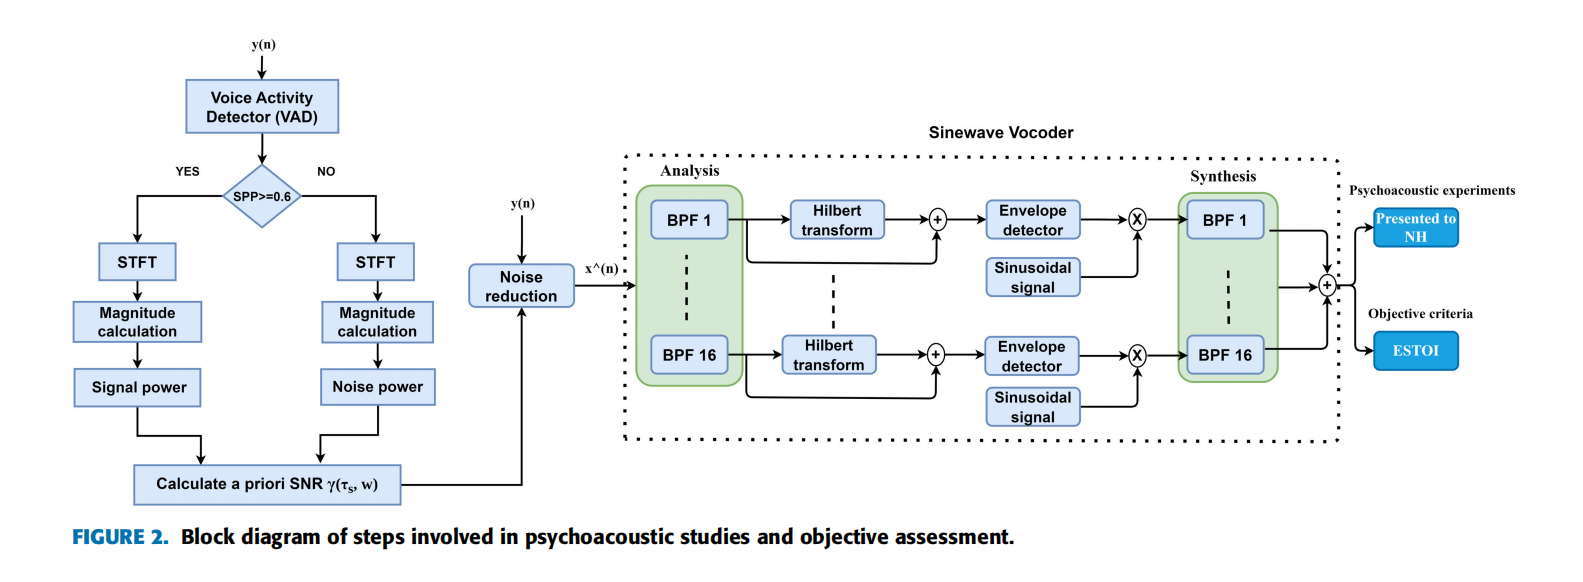

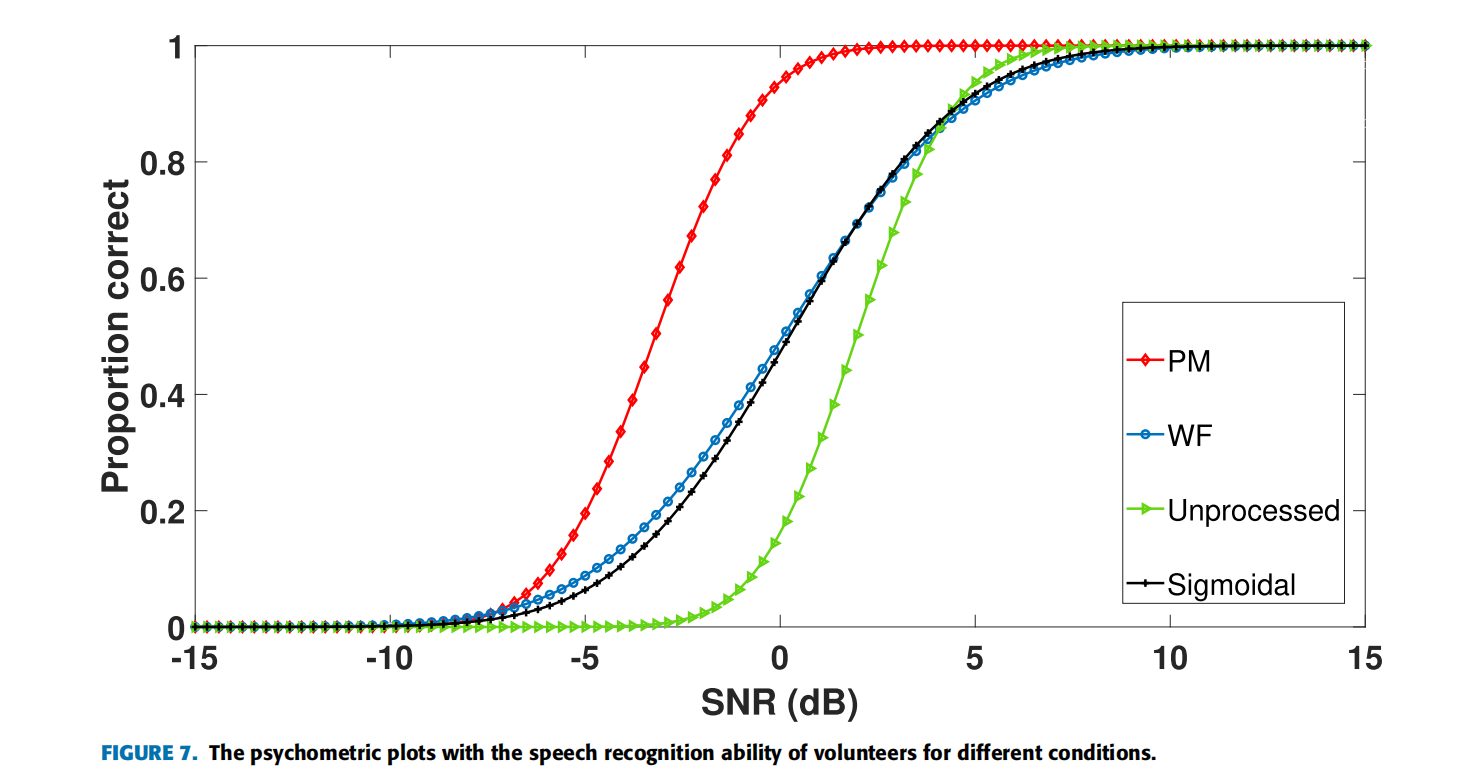

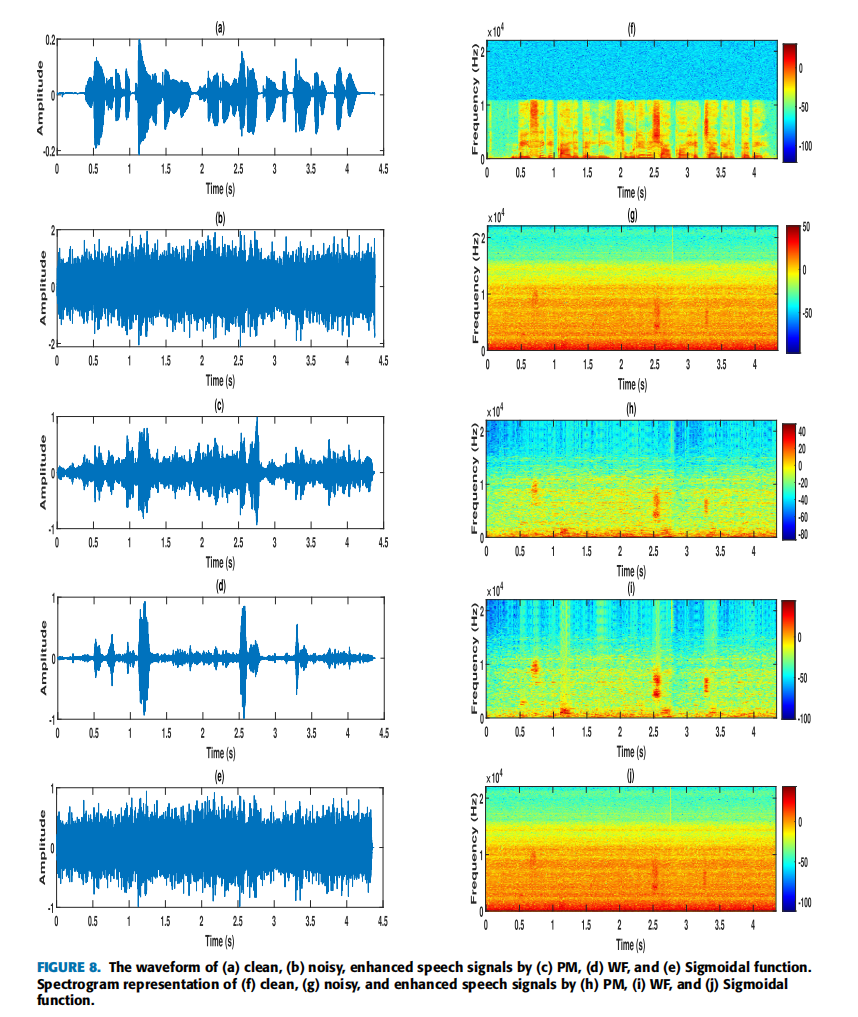

V. Poluboina, A. Pulikala and A. N. P. Muthu, "An Improved Noise Reduction Technique for Enhancing the Intelligibility of Sinewave Vocoded Speech: Implication in Cochlear Implants," in IEEE Access, vol. 11, pp. 787-796, 2023, doi: 10.1109/ACCESS.2022.3232549.

**Conclusion**

    In a speech synthesis system, the number of frequency bands and the cut-off frequency of the LPF have a significant impact on the final speech synthesis results. 

    When the number of frequency bands is too low, the synthesized speech signal may lose information from the original signal, leading to poor restoration. Conversely, an excessively high number of frequency bands can lead to signal distortion. Therefore, choosing an appropriate number of frequency bands is crucial for signal restoration.

    As the LPF cutoff frequency increases, the similarity between the synthesized signal and the original signal improves. Therefore, increasing the LPF cutoff frequency appropriately during signal synthesis can help prevent the loss of information from the original signal.

    Furthermore, when the number of frequency bands and the LPF cutoff frequency are appropriately chosen, the orders of the BPF and LPF, as well as the frequency of the sine waves used for fine-tuning, do not have a significant influence on signal synthesis results. However, it is worth noting that excessively high filter orders can potentially be detrimental to the synthesized signal.

    For signals with SSN, the conclusions regarding the number of frequency bands and LPF cutoff frequency are similar to those for clean signals. However, for signals with noise, achieving a better synthesis outcome requires a higher number of frequency bands. Yet, in cases with a high SNR, even with a larger number of frequency bands, the final signal restoration may not match the quality of the restoration for clean signals. Therefore, in the design of artificial cochlear implants, effective noise removal can significantly enhance the performance of speech synthesis.

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function SSN=createSSN(x,fs)%上节课做的生成SSN
    x=x';
    sig=repmat(x,1,10);
    nfft=512;
    [Pxx,w]=pwelch(sig,hamming(nfft),nfft/2,nfft,fs);
    b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
    white_noise=1-2*rand(1,length(x)+3000);
    SSN=filter(b,1,white_noise);
    SSN=SSN(2000:end);
    %Discard the beginning which has little sound.
    SSN=SSN(1:length(x));
end

function [Fs,fsel]=createBandDivision(N,varargin)

    %输入想要获得多少个带
    %varargin是可选参数，可以不填或者填'min''max'
    %Fs是每个带的频率区间，每个元素都是二元素向量
    %fsel是每个区间的被选中用于以后乘sinewave的频率
    fmin=200;
    fmax=7000;
    dmin=log10(fmin/165.4+1)/0.06;
    dmax=log10(fmax/165.4+1)/0.06;
    D=linspace(dmin,dmax,N+1);
    F=zeros(1,N+1);
    for k=1:N+1
        F(k)=165.4*(10^(0.06*D(k))-1);
    end
    Fs=zeros(N,2);
    fsel=zeros(N,1);
    
    for k=1:N
        Fs(k,:)=[F(k),F(k+1)];
        if isempty(varargin)
            fsel(k)=(F(k)+F(k+1))/2;
        elseif isequal(varargin(1),{'min'})
            fsel(k)=F(k);
        elseif isequal(varargin(1),{'max'})
            fsel(k)=F(k+1);
        end
    end
end

function [Fs,fsel]=powerBandDivision(x,fs)
    x=x./norm(x);
    
end

function y=voiceSynthesize(x,N,n1,n2,fcut,fs,varargin)

    %输入音频x，切割带数N，n1带通滤波阶数，n2低通滤波阶数
    %varargin是可选参数，可以不填或者填'min''max'
    if isempty(varargin)||isequal(varargin(1),{'mid'})
        [Fs,fmid]=createBandDivision(N);
    else
        [Fs,fmid]=createBandDivision(N,string(varargin(1)));
    end

    y=zeros(1,length(x));
    %初始化信号长度，否则后面无法相加
    for k=1:N
        [b,a]=butter(n1,Fs(k,:)/(fs/2),"bandpass");
        
        y_filtered=filter(b,a,x);

        [b,a]=butter(n2,fcut/(fs/2),'low');
        %低通滤波取得包络，阶数为4
        y_env=filter(b,a,abs(y_filtered));

        sin_mid=sin(2*pi*fmid(k).*(xTime(x,fs)));
        y_mod=sin_mid.*y_env;
        y=y+y_mod;
        y=y./norm(y).*norm(x);
    end
end

function y=voiceEnvelope(x,N,n1,n2,fcut,fs,varargin)

    %输入音频x，切割带数N，n1带通滤波阶数，n2低通滤波阶数
    %varargin是可选参数，可以不填或者填'min''max'
    if isempty(varargin)||isequal(varargin(1),{'mid'})
        [Fs,~]=createBandDivision(N);
    else
        [Fs,~]=createBandDivision(N,string(varargin(1)));
    end

    y=zeros(1,length(x));
    %初始化信号长度，否则后面无法相加
    for k=1:N
        [b,a]=butter(n1,Fs(k,:)/(fs/2),"bandpass");
        
        y_filtered=filter(b,a,x);

        [b,a]=butter(n2,fcut/(fs/2),'low');
        %低通滤波取得包络，阶数为4
        y_env=filter(b,a,abs(y_filtered));

        y=y+y_env;
    end
    y=y./norm(y).*norm(x);
end


function y=noisySig(x,SSN,dB)
    y=x+SSN./norm(SSN).*norm(x)*10^(-dB/20);
    y=y./norm(y).*norm(x);
end

function plotSpectrogram(x,fs,Title)
    %信号x，采样率fs，标题（用''包裹的String）
    window = hamming(256); % 窗函数
    noverlap = 128; % 重叠样本数
    nfft = 512; % FFT点数
    figure
    spectrogram(x, window, noverlap, nfft, fs, 'yaxis')
    title(Title);
    colorbar;
    xlabel('Time(s)');
    ylabel('Frequency(Hz)');
end

function plotTimeGraph(x,fs,a,n,Title)
    %subplot(a,1,n)
    if n==1
        figure
        set(gcf, 'Position', [100, 100, 400, 600]);
    end
    subplot(a,1,n),plot(xTime(x,fs),x),subtitle(Title),ylim([-0.3,0.3])
    if n==1
        title('Time Domain')
    end
    if n==a
        xlabel('t(s)')
        %只在最下面标出横轴坐标，节约空间
    end
end

function plotSpectrum(x,fs,a,n,Title)
    if n==1
        figure
        set(gcf, 'Position', [100, 100, 400, 600]);
    end
    tau=1/fs;
    N=length(x);
    w=(1-N)*pi/N/tau+(0:N-1)*2*pi/N/tau;
    subplot(a,1,n),plot(w/(2*pi),fftshift(abs(tau*fft(x)))),subtitle(Title)
    if n==1
        title('Frequency Domain')
    end
    if n==a
        xlabel('f(Hz)')
    end
end
